1) Calculating Acceleration from Velocity

v = [0, 6, 8, 2, 2, 4, -2];
t = [0, 20, 40, 50, 70, 90, 100];
%homegrown function
[a,xc] = Der(v,t);

xc =      0    20    40    50    70    90


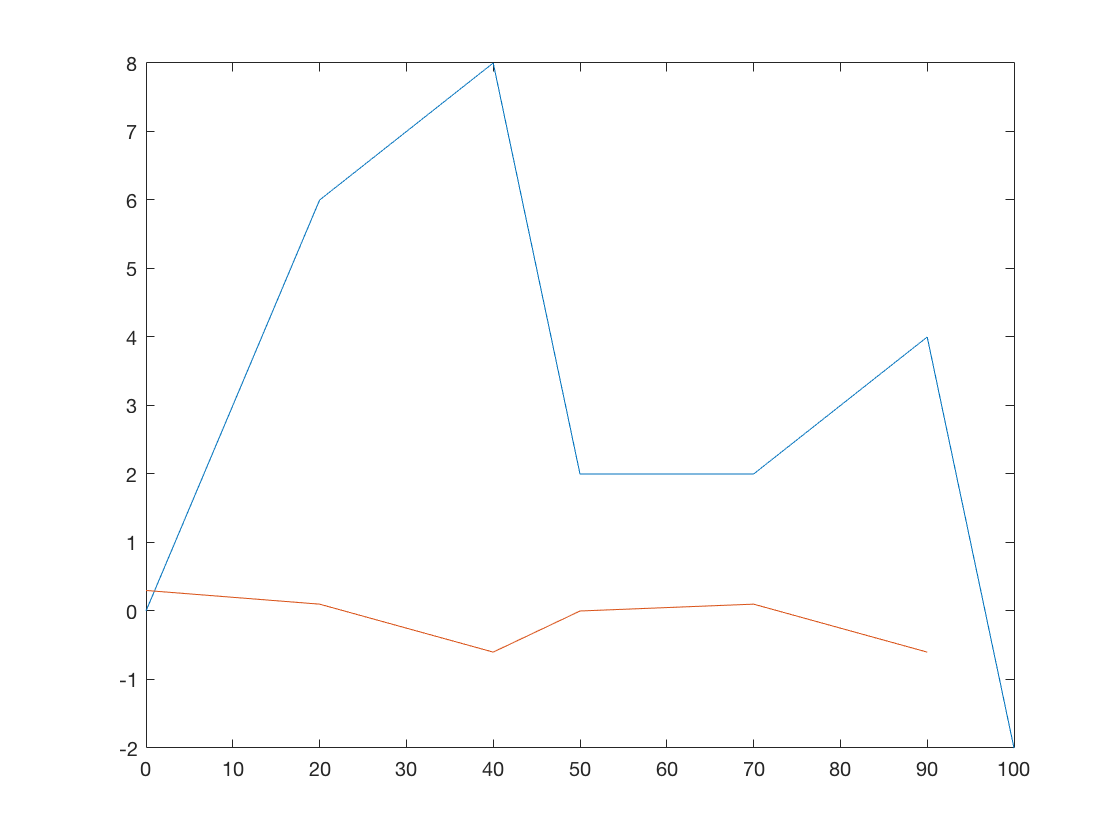

%built-in function

plot(t, v, xc, a)

Displacement

%homegrown function

%built-in function
trapz(t, v)

ans =    360


2 )$f\left(x\right)={\mathrm{sin}}^2 \left(\frac{1}{x\left(2-x\right)}\right)$

F = @(x) (sin(1./(x.*(2-x)))).^2;
i = [0:.01:3];
%calculate derivative
[dy,xc] = Der(F,i)

xc =             0         0.01         0.02         0.03         0.04         0.05         0.06         0.07         0.08         0.09          0.1         0.11         0.12         0.13         0.14         0.15         0.16         0.17         0.18         0.19          0.2         0.21         0.22         0.23         0.24         0.25         0.26         0.27         0.28         0.29          0.3         0.31         0.32         0.33         0.34         0.35         0.36         0.37         0.38         0.39          0.4         0.41         0.42         0.43         0.44         0.45         0.46         0.47         0.48         0.49


dy =       -41.839       60.602       28.973      -12.611       2.2168      -86.248       98.479      -63.094      -34.033       45.278        43.28       8.5197      -17.603      -26.939      -24.787      -17.591      -9.5202      -2.5648       2.6356       6.1139       8.1666       9.1457       9.3695       9.0937       8.5101        7.756       6.9257       6.0818       5.2638        4.495       3.7882       3.1484       2.5762       2.0693       1.6236       1.2343      0.89596      0.60349      0.35183      0.13628    -0.047448     -0.20326     -0.33466     -0.44475     -0.53627     -0.61167     -0.67307     -0.72233      -0.7611     -0.79079


xc =             0         0.01         0.02         0.03         0.04         0.05         0.06         0.07         0.08         0.09          0.1         0.11         0.12         0.13         0.14         0.15         0.16         0.17         0.18         0.19          0.2         0.21         0.22         0.23         0.24         0.25         0.26         0.27         0.28         0.29          0.3         0.31         0.32         0.33         0.34         0.35         0.36         0.37         0.38         0.39          0.4         0.41         0.42         0.43         0.44         0.45         0.46         0.47         0.48         0.49




syms g(y)
g(y) = (sin(1/(y*(2-y))))^2;
b = diff(g, y);

c = int(g, y)

$$c(y) = \int {\sin\left(\frac{1}{y\,\left(y-2\right)}\right)}^{2}\mathrm{d}y$$


y=(.001:.001:3);
z = eval(b)

z =   -4.9765e+05   1.0432e+05       -40818        22984        10635       8556.6       9331.9       1257.7       6149.5       142.24       1243.5      -2896.4      -2654.4       -813.4       2068.7      -334.61      -613.38       724.27      -370.34      -296.57       954.23      -948.55      -1.6828       843.31       -262.5       -706.1       106.02       634.87       249.19      -364.81      -507.54      -163.81       260.88       431.17       294.41       4.8628      -245.61      -343.56       -279.7      -115.13       68.369       205.69       264.63       244.75       166.87       60.657      -45.501      -130.48       -182.6      -199.01


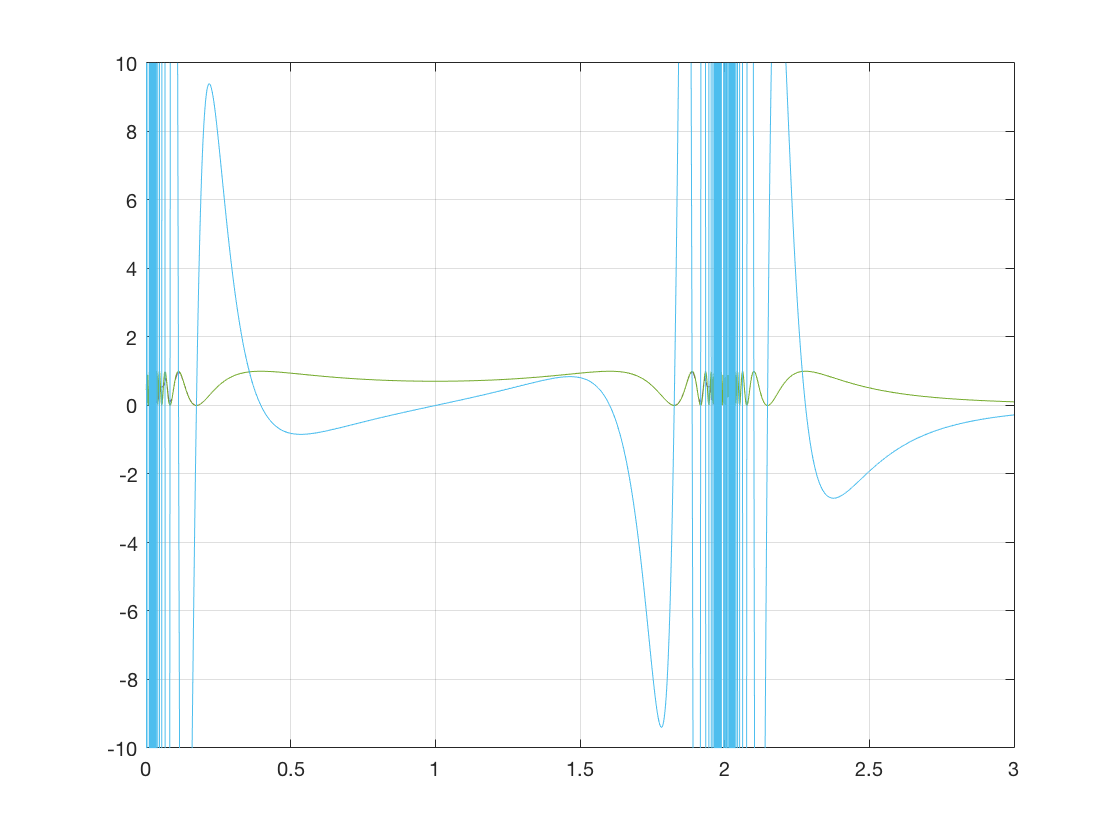

%z = subs(g, y, h)
plot(y, F(y), y, z)
grid on

%{
hold on
axis([0 3 -10 10])
h2 = (.001:.001:2);
u = subs(c,y,h2);
plot(h, u)
%}
%calculate integral



3) Calculating Integrals


$$\int_0^{\pi } \mathrm{sin}\left(x^2 \right)\mathrm{dx}$$


f = @(x) sin(x.^2);
%homegrown function

%built-in function
F = integral(f, 0, pi)

F =       0.77265


%romberg method

%{
syms f(x)
f(x) = sin(x^2)

$$f(x) = \sin\left(x^{2}\right)$$

G = eval(int(f, [0 pi]))

G =       0.77265


%}


$$\int_0^{\pi } {\mathrm{sin}}^2 \left(x^2 \right)\mathrm{dx}$$


f = @(x) (sin(x.^2)).^2;
%homegrown function

%built-in function
F = integral(f, 0, pi)

F =         1.319


%romberg method


$$\int_1^{e^{\pi /2} } \cos \left(\mathrm{ln}\left(x\right)\right)\textrm{dx}$$


f = @(x) cos(log(x));
%homegrown function

%built-in function
F = integral(f, 1, exp(1)^(pi/2))

F =        1.9052


 
$$\int_1^{2\pi } \frac{\mathrm{sin}\left(x\right)}{\mathrm{ln}\left(x\right)}\textrm{dx}$$


f = @(x) sin(x)./log(x);
%homegrown function

%built-in function
F = integral(f, 1, 2*pi)

F =        32.219
